% Uppgift 1.1 

load TRC_display.mat

val = 0:0.01:1;

plot(TRCb, 'b');
hold on
plot(TRCg,'g');
hold on
plot(TRCr, 'r');

% vår linjära input
plot(val, 'k')
hold on

 % Uppgift 1.2

load Ramp_display.mat
load Ramp_linear.mat

imshow(Ramp_display) 

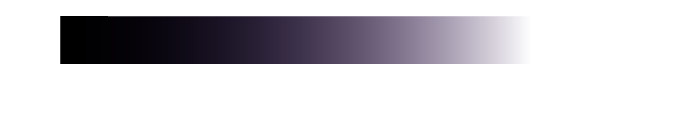


imshow(Ramp_linear)


TRCMatrix(:,:,1) = TRCr;
TRCMatrix(:,:,2) = TRCg;
TRCMatrix(:,:,3) = TRCb;

%använder vår funktion 
linearized_image = linearization(TRCMatrix, Ramp_display);

imshow(linearized_image)


% Uppgift 1.3
%gamma korrektion 

yr = 2.1;
yg = 2.4;
yb = 1.8;

%För att våra RGB-värden redan är normaliserade till intervallet 0 till 1
%Dmax = 1;

%Ekvation 4: Dr = Dmax(D'R/Dmax)^(1/yr), dmax inte med eftersom = 1
D(:,:,1) = (Ramp_display(:,:,1).^(1/yr));
D(:,:,2) = (Ramp_display(:,:,2).^(1/yg));
D(:,:,3) = (Ramp_display(:,:,3).^(1/yb));

imshow(D);


% Uppgift 2.1

load DLP.mat

lamda = 400:5:700;

figure;

%spectrialt ljus för rgb 

plot(lamda, DLP(:,1), 'r');
hold on
plot(lamda, DLP(:,2), 'g');
hold on 
plot(lamda, DLP(:,3), 'b');
hold off


% Uppgift 2.2


load RGB_raw.mat;
load illum.mat;
load xyz.mat;
load chips20.mat;

% for loop för att hitta vårt SRGB för alla 20 färgprover
lam = 20;
SRGB = zeros(61, lam);

for s = 1:lam

SRGB(:,s) = RGB_raw(1,s)*DLP(:,1)+ RGB_raw(2,s)*DLP(:,2)+ RGB_raw(3,s)*DLP(:,3);

end

plot(SRGB)

% normaliseringsfaktor, precis som i lab1 
k = 100./(CIED65*xyz(:,2));

%räknar ut estimerade
XYZ_est = k * xyz' * SRGB; 

% räkna ut våra ref XYZ
XYZ_D65_ref = xyz'*( chips20.*CIED65)' .* k;


diff = colordiffernce(XYZ_D65_ref, XYZ_est);
mean(diff)
max(diff)


% Uppgift 2.3 

load RGB_cal.mat;

lam = 20;
SRGB2 = zeros(61, lam);

for s = 1:lam

SRGB2(:,s) = RGB_cal(1,s)*DLP(:,1)+ RGB_cal(2,s)*DLP(:,2)+ RGB_cal(3,s)*DLP(:,3);

end

plot(SRGB2);

% normaliseringsfaktor, precis som i lab1 
%k = 100./(CIED65*xyz(:,2));

%räknar ut estimerade
XYZ_est2 = k * xyz' * SRGB2; 

diff = colordiffernce(XYZ_D65_ref, XYZ_est2);
mean(diff)
max(diff)


% Uppgift 3.1
% givet en XYZ-färg vilka RGB-värden ska vi skicka till projektorn

% korrekta normaliseringfaktorn 
k = 100./(CIED65*xyz(:,2));

Acrt = xyz'*DLP*k;


% Uppgift 3.2

% våra bra xyz värden
load XYZ_est_poly.mat   % 20x3
XYZ_est_poly = XYZ_est_poly';   % 3x20

% XYZ -> RGB (output inverse characterization)
RGB_proj = inv(Acrt) * XYZ_est_poly;   

% RGB projektorns spektrum genom att * med DLP 
SRGB = DLP * RGB_proj;                 

% Från Spektrum till XYZ anpassade för projektorn
XYZ_SRGB = k * xyz' * SRGB;            

% Color difference
diff = colordiffernce(XYZ_D65_ref, XYZ_SRGB);
mean(diff)
max(diff)

% Uppgift 3.3

% rgb värden för projektorn  
min(RGB_proj(:))
max(RGB_proj(:))

[min(RGB_proj,[],2), max(RGB_proj,[],2)]

%RGB-värden ska ligga i [0, 1] för en fysisk projektor
%det ser vi inte stämmer här 
% inversoner ger ogiltiga värden

% Uppgift 3.4

% "klipper" värderna så dom håller mig mellan 0 o 1
RGB_clip = min(max(RGB_proj, 0), 1);

% skapar en ny srgb 
SRGB_clip = DLP * RGB_clip;

XYZ_clip = k * xyz' * SRGB_clip;

diff_clip = colordiffernce(XYZ_D65_ref, XYZ_clip);
mean(diff_clip)
max(diff_clip)


% Uppgift 3.5

disp('Chromacity coordinates')

%Acrt - blå
%sRGB - svart
plot_chrom_sRGB(Acrt)

% hörn 1 = röd
% hörn 2 = grön
% hörn 3 = blå 
% bågen = det ögat kan uppfatta

%Projektorns gamut är mindre än sRGB.


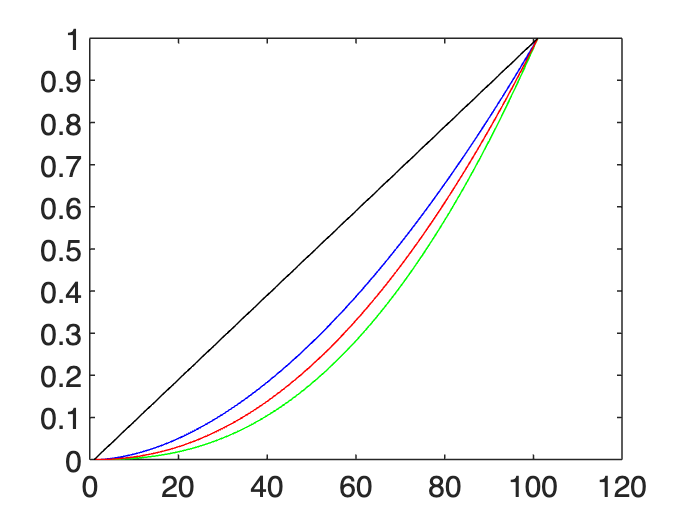

% Uppgift 3.6 

i = 7;

% Detta är den verkliga färgen 
spec_ref = chips20(i,:) .* CIED65;

% Spektral data (projektorns återgivning) från 3.4
spec_rep = SRGB_clip(:,i);

lambda = 400:5:700;


figure;
plot(lambda, spec_ref, 'k');
hold on
plot(lambda, spec_rep, 'r');

xlabel('Wavelength (nm)')
ylabel('Spectral power')